# Exercise #3 WLAN Custom Channel Model

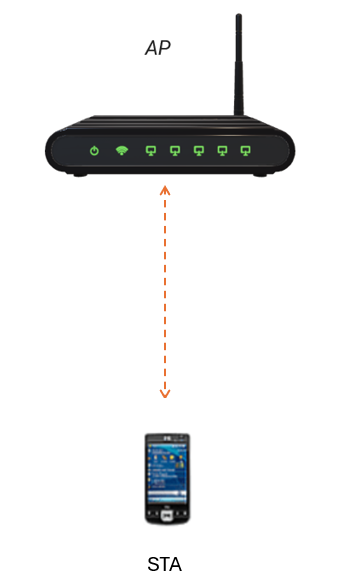

- Implement a channel model in 1/R^3

Copyright 2024-2025 The MathWorks, Inc

clear;
format default;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows 

### Physical constants and environment

band    = 5;
channel = 36;
channelBandwidth    = 20e6;
fc      = wlanChannelFrequency(channel,band)

TU              = 1024e-6;
simulationTime  = 10*TU

txPower = 0.0;
txGain  = 0.0;

APPosition  = [0,0,0];
STAPosition = [1, 1, 0];
D = norm(STAPosition-APPosition);

### Create an instance of Wireless Network Simulator

networkSimulator = wirelessNetworkSimulator.init;

### Attenuation in 1/R^3

- Reference value


$$\textrm{pathLoss}={\left(\frac{4\pi R}{\lambda }\right)}^3$$


attR3 = 10*log10(((4*pi*D)/(3e8/fc))^3)
[dist, atten] = plotNodesPositions(APPosition,STAPosition,fc);

### Create AP

- 802.11n type

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",channelBandwidth,...
    "TransmitPower",txPower, ...
    "TransmitGain",txGain, ...
    "MCS",3, ...
    "BeaconInterval",1, ...
    "InitialBeaconOffset",0);

AP = wlanNode(...
    "Name","AP",...
    "Position",APPosition, ...
    "DeviceConfig",APCfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Create STA

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","Non-HT", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",channelBandwidth,...
    "TransmitPower",txPower, ...
    "MCS",3, ...
    "ReceiveGain",0);

STA = wlanNode(...
    "Name","STA",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Associate AP with STA

associateStations(AP,STA)

# Task #1/2 Add Custom Channel Model to Network Simulator

% Use addChannelModel() function to define a function implementing a propagation channel model
% Hint: Click the link below and see the "Syntax" section.

### [Help on adding custom channel ](https://www.mathworks.com/help/releases/R2024b/comm/ref/wirelessnetworksimulator.addchannelmodel.html)

% Note : name the function implement the channel "myCustomChannel". To
% pass the function as an argument use @myCustomChannel 

% <enter code below>


% Goto the end of this script to define myCustomchannel () function

#### Run the simulation

addNodes(networkSimulator,{AP, STA})
run (networkSimulator,simulationTime)

networkSimulator.ChannelFunction

### Visualize statistics

STAStatistics = statistics(STA);
STAStatistics.MAC

#### Custom channel

Follow these steps to create a custom channel model

- The simulator passes information about the receiver node and transmitter node as inputs to the custom function.

- Apply free space path loss between the base station and UE nodes. 

- Apply custom channel to the transmitted packets.

# Task #2/2 Implement custom path loss for the channel 

% myCustomChannel is a user-defined callback function invoked by the simulation engine
% whenever a packet is exchanged between any two nodes in the simulated network.

% rxInfo that passed to this function constains the following information
% ID
% Position
% Velocity and more ..

% txData that is passed function constains the following information
% TransmitterID
% TransmitterPosition
% TransmitterVelocity
% Power
% CenterFrequency
% Bandwidth
% Sample rate
% Antenna Configuration
% Tx Data and more ..
function outputData = myCustomChannel(rxInfo,txData)
outputData = txData;
%%%%%%%%%%%%%%%%%%%%%%%%%% Large Scale Fading %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Wavelength calculation using the speed of light and center frequency.
% Hint: see the contents of txData.CenterFrequency
% name the variable "lambda"
SpeedOfLight = physconst('LightSpeed');
lambda = SpeedOfLight/txData.CenterFrequency;

% Use norm() function to compute distance between UE and gNB
% Distance = norm(p1 - p2) where p1 = (x1, y1, z1) and p2 = (x2, y2, z2)
% For points p1 and p2, this calculates sqrt((x1-x2)^2 + (y1-y2)^2 + (z1-z2)^2)
% Hint: see the contents of outputData.TransmitterPosition, rxInfo.Position
% name the variable "distance"

% Write your code here
% distance = 

% Calculate Free space path loss
% Use the function fspl()
% Hint:Type doc fspl in the command window, and see the "Syntax" section.
% name the variable "pathLoss"
% Note : use the following arguments 
% distance 
% lambda

% Write your code here
% pathLoss = 

% Apply path loss on the power of the packet
outputData.Power = outputData.Power - pathLoss;

if outputData.Abstraction == 0
    % Apply the path loss effect on IQ samples
    scale = 10.^(-pathLoss/20);
    [numSamples, ~] = size(outputData.Data);
    outputData.Data(1:numSamples,:) = outputData.Data(1:numSamples,:)*scale;
end

% Set Metadata
outputData.Metadata.Channel.PathGains   = 1;
outputData.Metadata.Channel.PathDelays  = 0;
outputData.Metadata.Channel.PathFilters = 1;
outputData.Metadata.Channel.SampleTimes = 0;

%disp(outputData.Metadata.Channel)
end